# Taller 1

### 26/06/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 1 y 2*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @.

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

### Fundamentos de MATLAB

*Desarrollaremos el primer taller, para esta primera sección resolveremos *$\left.\left.2\right)\;\&\;4\right)$

**2. **Considere las funciones $f\left(x\right)=\;\frac{x}{1+x^2 }$ y $g\left(x\right)=\tan \left(x\right)$ Escriba un código MATLAB que calcule tanto estas dos funciones como las funciones compuestas $f\left(g\left(x\right)\right)$ y $g\left(f\left(x\right)\right)$ en una malla o subdivisión del intervalo $\left\lbrack -1,1\right\rbrack$ . Dicha subdivisón se puede obtener por medio del comando `linspace`, por ejemplo, `I = linspace(-1,1`) 

clear

% Definición por Puntos
x = linspace(-1, 1, 100); % Espacio equiespaciado de valores
f = x ./ (1 + x.^2) % Operación por cada elemento

f =    -0.5000   -0.4999   -0.4996   -0.4990   -0.4982   -0.4972   -0.4959   -0.4942   -0.4923   -0.4901   -0.4875   -0.4846   -0.4813   -0.4777   -0.4736   -0.4691   -0.4642   -0.4588   -0.4529   -0.4466   -0.4398   -0.4324   -0.4245   -0.4161   -0.4071   -0.3976   -0.3874   -0.3767   -0.3654   -0.3535   -0.3410   -0.3279   -0.3143   -0.3000   -0.2852   -0.2698   -0.2538   -0.2374   -0.2204   -0.2030   -0.1851   -0.1668   -0.1481   -0.1291   -0.1098   -0.0902   -0.0704   -0.0504   -0.0303   -0.0101


g = tan(x)

g =    -1.5574   -1.4903   -1.4271   -1.3675   -1.3111   -1.2575   -1.2067   -1.1582   -1.1120   -1.0678   -1.0255   -0.9849   -0.9458   -0.9083   -0.8721   -0.8371   -0.8033   -0.7706   -0.7389   -0.7081   -0.6782   -0.6491   -0.6208   -0.5931   -0.5661   -0.5398   -0.5140   -0.4887   -0.4639   -0.4396   -0.4157   -0.3922   -0.3690   -0.3463   -0.3238   -0.3016   -0.2797   -0.2580   -0.2366   -0.2154   -0.1943   -0.1734   -0.1527   -0.1321   -0.1116   -0.0912   -0.0708   -0.0505   -0.0303   -0.0101


fog = g ./ (1 + g.^2) % Compuesta fog

fog =    -0.4546   -0.4627   -0.4700   -0.4765   -0.4822   -0.4872   -0.4913   -0.4947   -0.4972   -0.4989   -0.4998   -0.4999   -0.4992   -0.4977   -0.4954   -0.4922   -0.4882   -0.4835   -0.4780   -0.4716   -0.4645   -0.4567   -0.4481   -0.4388   -0.4287   -0.4180   -0.4066   -0.3945   -0.3817   -0.3684   -0.3544   -0.3399   -0.3248   -0.3092   -0.2931   -0.2765   -0.2594   -0.2419   -0.2241   -0.2058   -0.1872   -0.1684   -0.1492   -0.1298   -0.1102   -0.0904   -0.0705   -0.0504   -0.0303   -0.0101


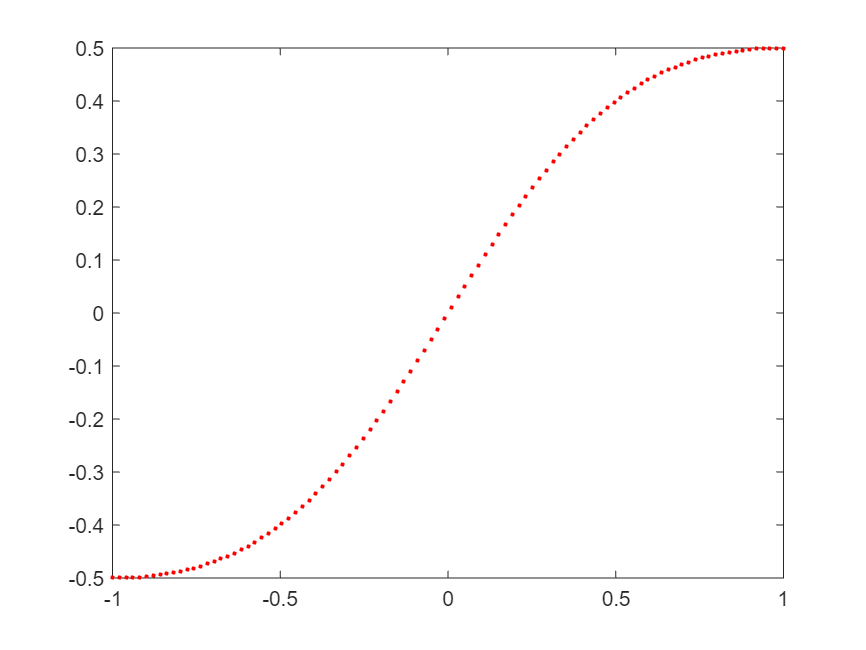

plot(x, f, '.r')

clear

% Definir funciones de matlab
f = @(x) x ./ (1 + x.^2) % Definición de código

f = function_handle with value:
    @(x)x./(1+x.^2)


g = @(x) tan(x)

g = function_handle with value:
    @(x)tan(x)


fog = @(x) f(g(x))

fog = function_handle with value:
    @(x)f(g(x))


fog(-1)

ans = -0.4546

help diff

 diff Difference and approximate derivative.
    diff(X), for a vector X, is [X(2)-X(1)  X(3)-X(2) ... X(n)-X(n-1)].
    diff(X), for a matrix X, is the matrix of row differences,
       [X(2:n,:) - X(1:n-1,:)].
    diff(X), for an N-D array X, is the difference along the first
       non-singleton dimension of X.
    diff(X,N) is the N-th order difference along the first non-singleton 
       dimension (denote it by DIM). If N >= size(X,DIM), diff takes 
       successive differences along the next non-singleton dimension.
    diff(X,N,DIM) is the Nth difference function along dimension DIM. 
       If N >= size(X,DIM), diff returns an empty array.
 
    Examples:
       h = .001; x = 0:h:pi;
       diff(sin(x.^2))/h is an approximation to 2*cos(x.^2).*x
       diff((1:10).^2) is 3:2:19
 
       If X = [3 7 5
               0 9 2]
       then diff(X,1

% Intentemos usar derivadas para las funciones
f = @(x) diff(f, x)

f = function_handle with value:
    @(x)diff(f,x)


% f(2) Error al evaluar

Check for incorrect argument data type or missing argument in call to function 'diff'.

Error in [Semana 1]Taller (line 18)
f = @(x) diff(f, x)

clear
syms f(x) g(x)

% Definir funciones simbolicas
f(x) = x / (1 + x^2)

$$f(x) = \frac{x}{x^{2}+1}$$

f([1, 2, 3])

$$ans = \left(\begin{array}{ccc} \frac{1}{2} & \frac{2}{5} & \frac{3}{10} \end{array}\right)$$

g(x) = tan(x)

$$g(x) = \tan\left(x\right)$$

fog(x) = f(g(x))

$$fog(x) = \frac{\tan\left(x\right)}{{\tan\left(x\right)}^{2}+1}$$

fog(-1)

$$ans = -\frac{\tan\left(1\right)}{{\tan\left(1\right)}^{2}+1}$$

help diff

 diff Difference and approximate derivative.
    diff(X), for a vector X, is [X(2)-X(1)  X(3)-X(2) ... X(n)-X(n-1)].
    diff(X), for a matrix X, is the matrix of row differences,
       [X(2:n,:) - X(1:n-1,:)].
    diff(X), for an N-D array X, is the difference along the first
       non-singleton dimension of X.
    diff(X,N) is the N-th order difference along the first non-singleton 
       dimension (denote it by DIM). If N >= size(X,DIM), diff takes 
       successive differences along the next non-singleton dimension.
    diff(X,N,DIM) is the Nth difference function along dimension DIM. 
       If N >= size(X,DIM), diff returns an empty array.
 
    Examples:
       h = .001; x = 0:h:pi;
       diff(sin(x.^2))/h is an approximation to 2*cos(x.^2).*x
       diff((1:10).^2) is 3:2:19
 
       If X = [3 7 5
               0 9 2]
       then diff(X,1

% Derivemos
df(x) = diff(f, x)

$$df(x) = \frac{1}{x^{2}+1}-\frac{2\,x^{2}}{{\left(x^{2}+1\right)}^{2}}$$

df(0)

$$ans = 1$$

**4. **Utilice el comando `fplot` para dibujar la función $f\left(x\right)=\frac{1}{\cos \left(\pi x\right)}$ para $x\in \left\lbrack -3,3\right\rbrack$ . Lo importante de `fplot` es que detecta asintotas verticales

clear

x = linspace(-3, 3)

x =    -3.0000   -2.9394   -2.8788   -2.8182   -2.7576   -2.6970   -2.6364   -2.5758   -2.5152   -2.4545   -2.3939   -2.3333   -2.2727   -2.2121   -2.1515   -2.0909   -2.0303   -1.9697   -1.9091   -1.8485   -1.7879   -1.7273   -1.6667   -1.6061   -1.5455   -1.4848   -1.4242   -1.3636   -1.3030   -1.2424   -1.1818   -1.1212   -1.0606   -1.0000   -0.9394   -0.8788   -0.8182   -0.7576   -0.6970   -0.6364   -0.5758   -0.5152   -0.4545   -0.3939   -0.3333   -0.2727   -0.2121   -0.1515   -0.0909   -0.0303


f = 1 ./ cos(pi * x)

f =    -1.0000   -1.0184   -1.0772   -1.1887   -1.3817   -1.7240   -2.4072   -4.2416  -21.0164    7.0267    3.0575    2.0000    1.5270    1.2722    1.1251    1.0422    1.0045    1.0045    1.0422    1.1251    1.2722    1.5270    2.0000    3.0575    7.0267  -21.0164   -4.2416   -2.4072   -1.7240   -1.3817   -1.1887   -1.0772   -1.0184   -1.0000   -1.0184   -1.0772   -1.1887   -1.3817   -1.7240   -2.4072   -4.2416  -21.0164    7.0267    3.0575    2.0000    1.5270    1.2722    1.1251    1.0422    1.0045


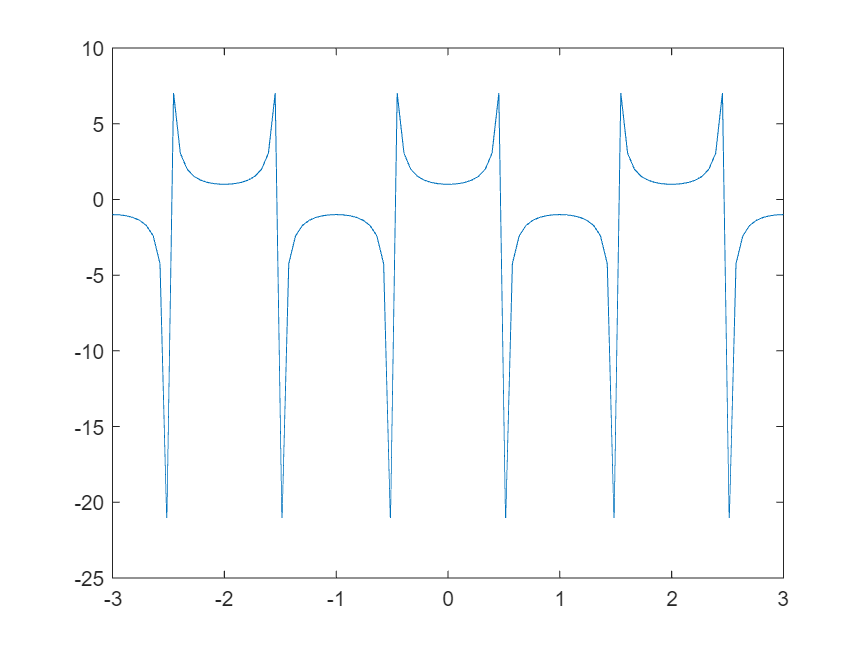

% Hallemos las gráficas sin asintotas
plot(x, f)

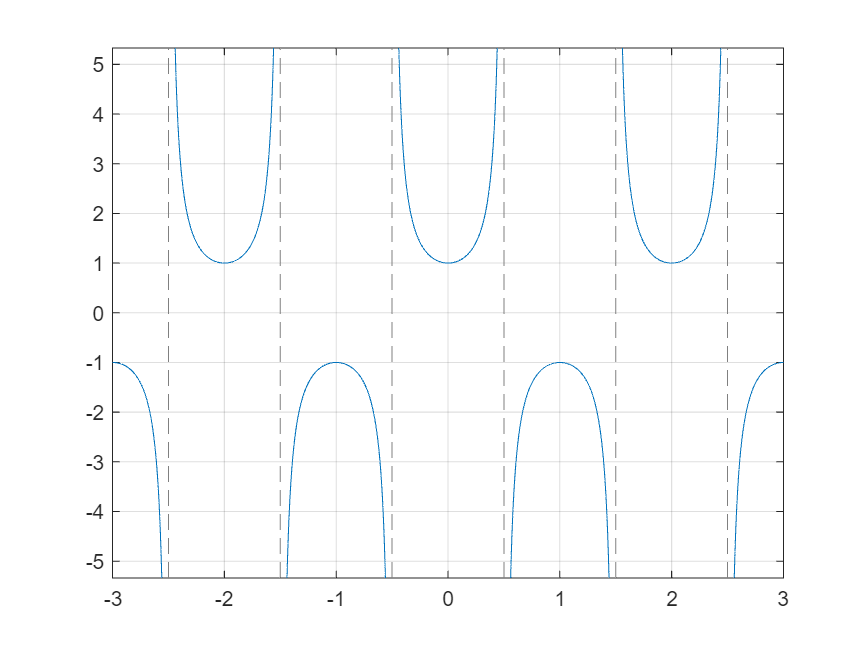

clear

f = @(x) 1 ./ cos(pi * x);

% Gráfiquemos identificando las asintotas de la función
fplot(f, [-3, 3])
grid on

### Algunos comentarios sobre MATLAB

*Desarrollemos un poco de código y veamos los detalles de trabajar con MATLAB*

help bisect

  Entrada - f es la funcion introducida con @
 	      - a y b son los extremos izquierdo y derecho
 	      - delta es la tolerancia
  Salida  - c es el cero
 	      - yc = f(c)
  	      - err es el error estimado para  c



% For : Ciclo 'para'
Numero = 0

Numero = 0

for k=1:10
    Numero =  k
end

Numero = 1

Numero = 2

Numero = 3

Numero = 4

Numero = 5

Numero = 6

Numero = 7

Numero = 8

Numero = 9

Numero = 10

% While : Ciclo 'mientras'
Numero = 0;
k = 0;
while Numero < 5
    k = k +1
    Numero = k
end

k = 1

Numero = 1

k = 2

Numero = 2

k = 3

Numero = 3

k = 4

Numero = 4

k = 5

Numero = 5

% if : Metodo 'si'
k = 10;
n = 5;
if n < 10
    disp(n)
end

     5



if k < 10
    disp(k)
end

### Bisección y Punto fijo

*Desarrollaremos el primer taller, para esta primera sección resolveremos *$\left.\left.\left.\left.6\right),8\right),\;9\right),11\right)$.

*Sobre punto fijo lo veremos desde la prox semana*

**6. **Hay ocasiones en que no es fácil aplicar el método de bisección por la dificultad para aislar raices en intervalos. Considere $f\left(x\right)=\;\cos \left(x\right)\;-\;\cos \left(3\ldotp 1\right)$, la cual tiene varios cambios de signo en el intervalo $\left\lbrack -1,8\right\rbrack$ . Realice 4 iteraciones del método de bisección para aproximar la menor raiz positiva de esta función.

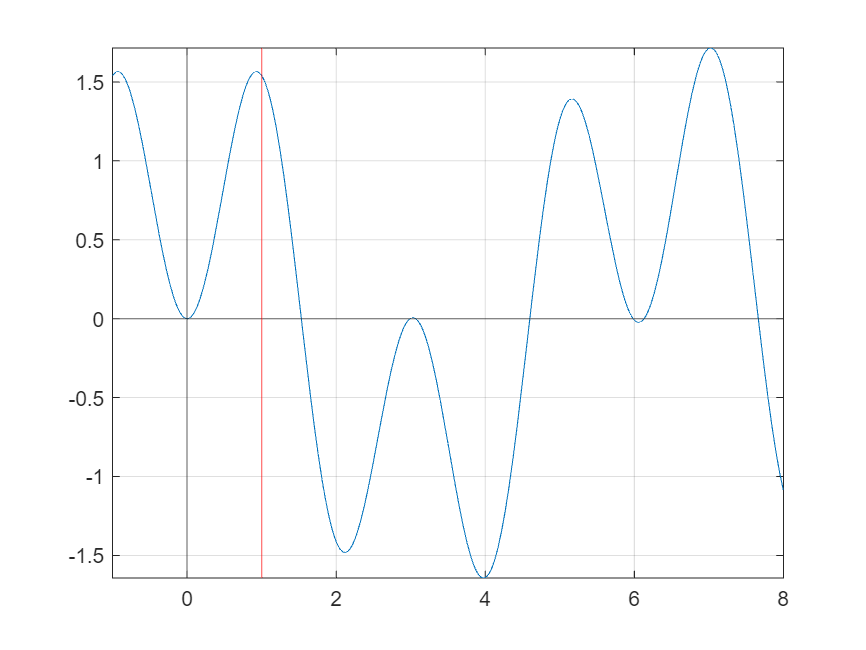

clear

f = @(x) cos(x) - cos(3.1*x); % Función

fplot(f, [-1, 8])
grid on
yline(0)
xline(0)
xline(1, 'r') % Linea de referencia

f(0) % Pero cero no es positivo

ans = 0

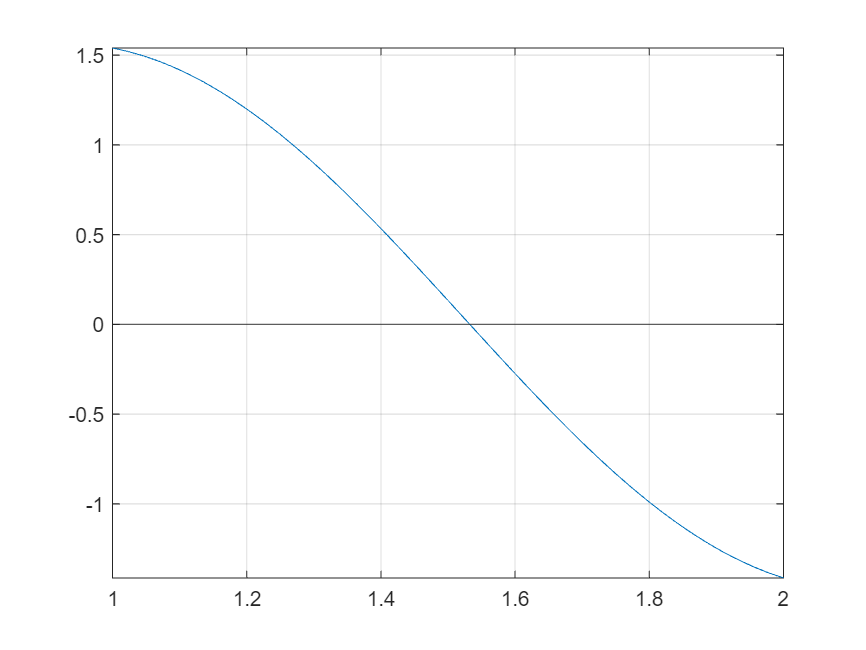

fplot(f, [1, 2])
grid on
yline(0)

help bisect

  Entrada - f es la funcion introducida con @
 	      - a y b son los extremos izquierdo y derecho
 	      - delta es la tolerancia
          - maxIter Maximo de iteración
  Salida  - c es el cero
 	      - yc = f(c)
  	      - err es el error estimado para  c



[c, yc, err] = bisect(f, 1, 2, 1e-18, 100)

k = 61

c = 1.5325

yc = 2.2204e-16

err = 2.4286e-16

#### Código usado

`function  [c, err, yc] = bisect (f, a, b, delta, maxIter)`

`% Entrada - f es la funcion introducida con @`

`%	      - a y b son los extremos izquierdo y derecho`

`%	      - delta es la tolerancia`

`%         - maxIter Maximo de iteración`

`% Salida  - c es el cero`

`%	      - yc = f(c)`

`% 	      - err es el error estimado para  c`

`%  METODOS NUMERICOS: Programas en Matlab`

`% (c) 2004 por John H. Mathews y Kurtis D. Fink`

`%  Software complementario acompa�ando al texto:`

`%  METODOS NUMERICOS con Matlab, Cuarta Edicion`

`%  ISBN: 0-13-065248-2`

`%  Prentice-Hall Pub. Inc.`

`%  One Lake Street`

`%  Upper Saddle River, NJ 07458`

`ya = feval(f, a);`

`yb = feval(f, b); % Evaluar la función f en b = f(b)`

`if  ya*yb > 0, return, end`

`max1 = 1 + round((log(b-a) - log(delta)) / log(2));`

`for  k = 1:max1`

`	c = (a + b) / 2;`

`	yc = feval(f, c);`

`	if  yc == 0`

`		a = c;`

`		b = c;`

`	elseif  yb*yc > 0`

`		b = c;`

`		yb = yc;`

`	else`

`		a = c;`

`		ya = yc;`

`	end`

`	if  b-a < delta, break, end`

`    if k == maxIter`

`        break`

`    end`

`end`

`c = (a + b) / 2;`

`err = abs(b - a);`

`yc = feval(f, c);`

`k`

**8. **Dibuje en la misma figura las funciones $y=x$ y $y=2\;\sin \left(x\right)$. Use el método de bisección con tolerancia `1e − 5` para aproximar el primer valor positivo de $x$ tal que $x=2\;\sin \left(x\right)$.

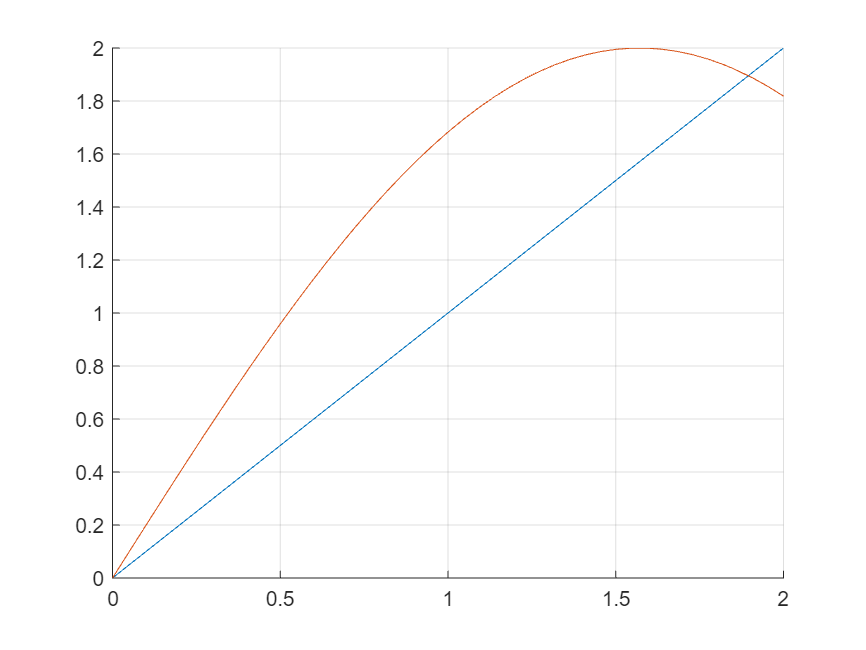

clear

f = @(x) x;
g = @(x) 2*sin(x);

clf('reset')
hold on
fplot(f, [0, 2])
fplot(g, [0, 2])
grid on
hold off

Reescribimos el problema:


$$f\left(x\right)=g\left(x\right)\to f\left(x\right)-g\left(x\right)=0:H\left(x\right)=0$$


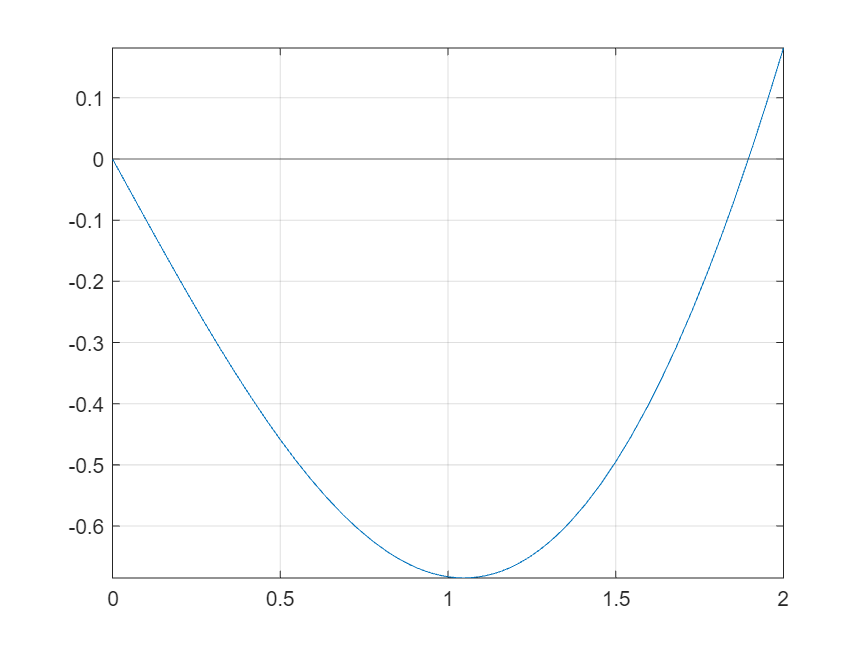

H = @(x) f(x) - g(x);

clf('reset')
fplot(H, [0, 2])
yline(0)
grid on

c = bisect(H, 1, 2, 1e-15, 100)

k = 50

c = 1.8955

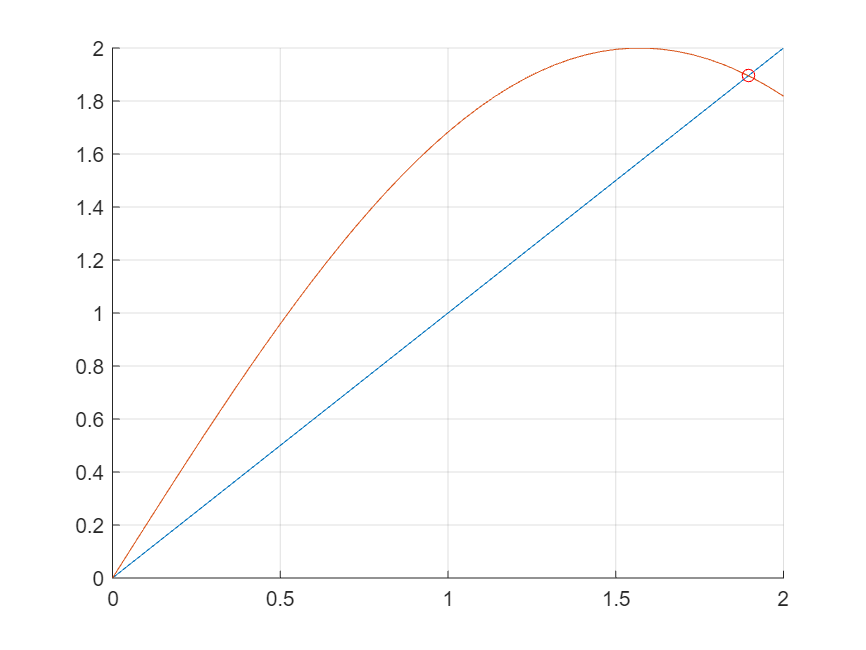

clf('reset')
hold on
fplot(f, [0, 2])
fplot(g, [0, 2])
plot(c, f(c), 'or')
grid on
hold off

**9. **Dibuje en la misma figura las funciones $y=e^x -2$ y $y=\cos \left(e^x -2\right)$. Use el método de bisección con tolerancia `1e − 5` para aproximar un valor$x\in \left\lbrack 0\ldotp 5,1\ldotp 5\right\rbrack$ tal que $e^x -2\;=\;\cos \left(e^x -2\right)$

clear

f = @(x) exp(x) - 2; % Cambio de variable : Asesoria
g = @(x) cos(exp(x) - 2);

h = @(x) f(x) - g(x);
c = bisect(h, .5, 1.5, 1e-5, 100)

k = 17

c = 1.0076

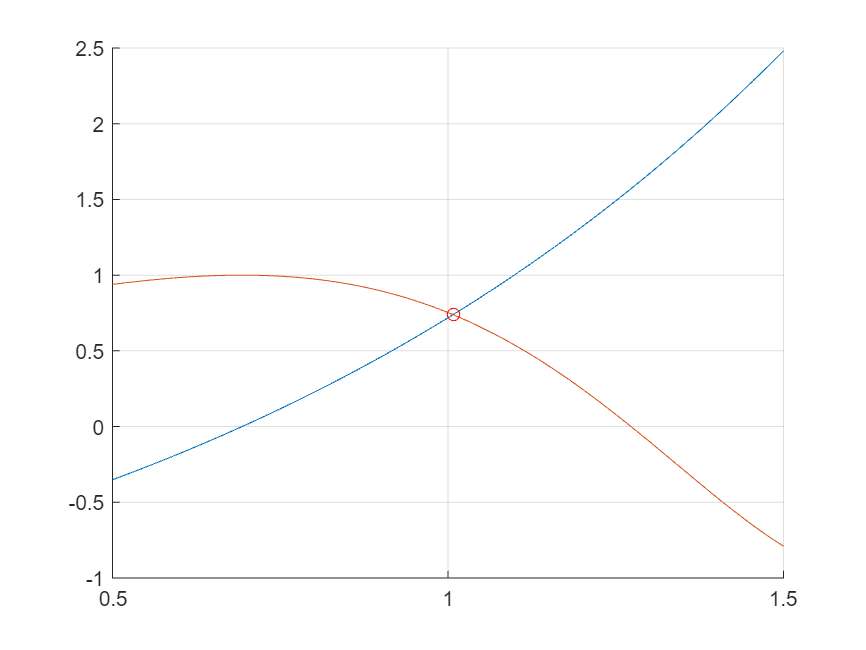

clf('reset')
hold on
fplot(f, [.5, 1.5])
fplot(g, [.5, 1.5])
plot(c, f(c), 'or')
grid on
hold off

**11. **Sea $f\left(x\right)=\left(x+2\right){\;\left(x+1\right)}^2 \;x\;{\left(x-1\right)}^3 \;\left(x-2\right)$. Establezca a qué cero de f converge el método de bisección cuando se aplica en cada uno de los siguientes intervalos.


$$a\ldotp \left\lbrack -3,2\ldotp 5\right\rbrack$$
            
$$b\ldotp \left\lbrack -2\ldotp 5,3\right\rbrack$$
                
$$c\ldotp \left\lbrack -1\ldotp 75,1\ldotp 5\right\rbrack$$
                
$$d\ldotp \left\lbrack -1\ldotp 5,1\ldotp 75\right\rbrack$$


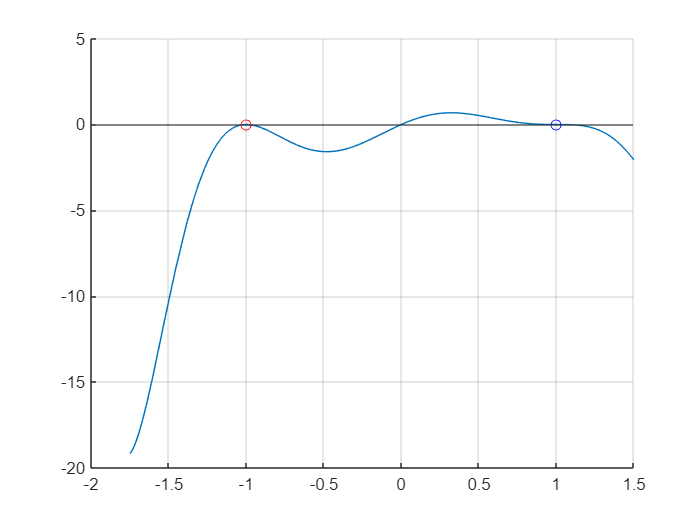

clear

f = @(x) (x + 2).* (x + 1).^2 .* x .* (x - 1).^3 .* (x - 2);

I = [-1.75, 1.5]; % No converge en el intervalo

clf('reset')
hold on
fplot(f, I)
plot(-1, 0, 'or') % Cero multiple
plot(1, 0, 'ob') % Cero multiple
yline(0)
grid on
hold off

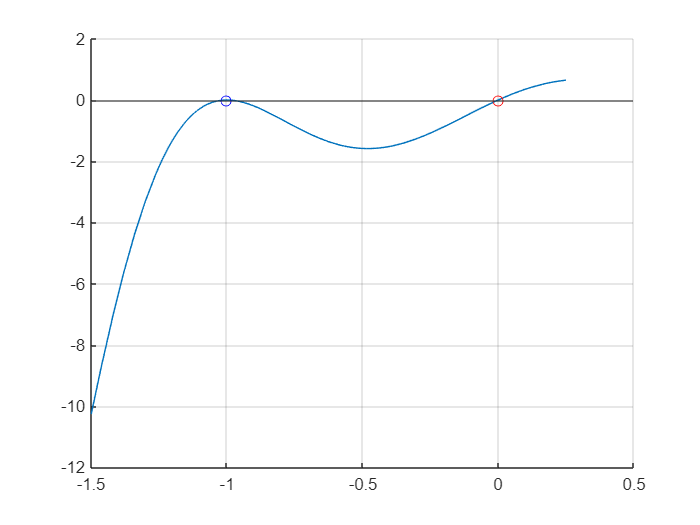

I = [-1.5, .25];

clf('reset')
hold on
fplot(f, I)
yline(0)
plot(-1, 0, 'ob')
plot(0, 0, 'or')
grid on
hold off